# Set up

data = (1:2)'; %each sample is a row (like a database row)
lr = 0.001;

tic;
alice = [0.5 0.5];
bob = [0.5 0.5];
numSamples = size(data, 1);

jDist = zeros(2,2);

## Compute joint distribution

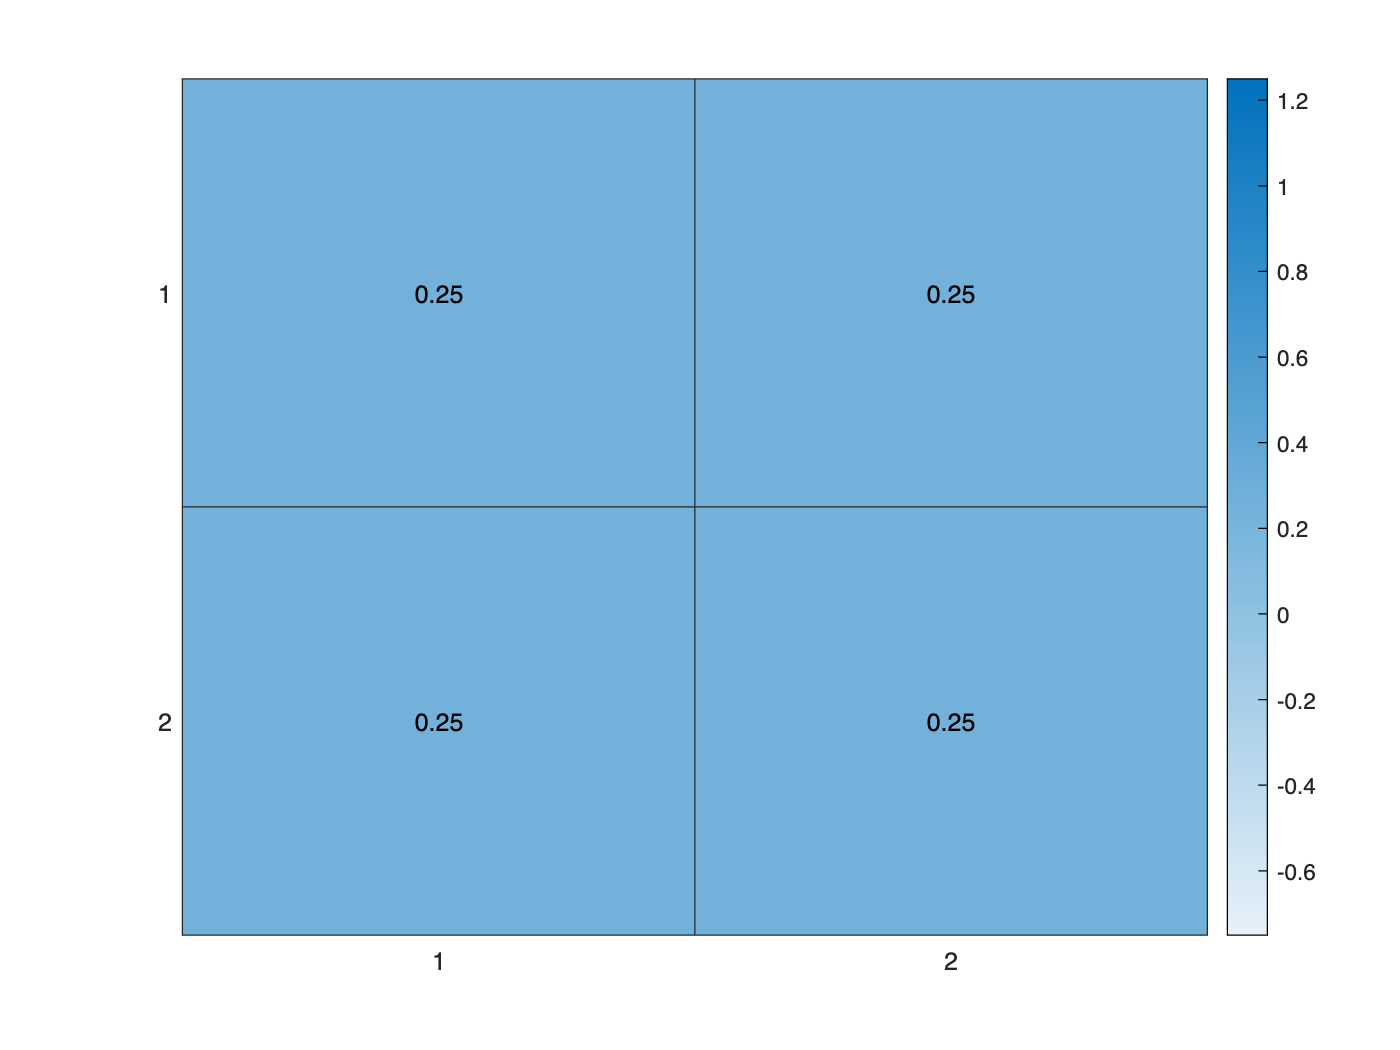

for sampleInd = 1:numSamples
    s = data(sampleInd,:);
    sampleJoint = [alice(s)*bob(s), alice(s)*(1-bob(s));
                         (1-alice(s))*bob(s), (1-alice(s))*(1-bob(s))];
    jDist = jDist  + sampleJoint / numSamples;
end
heatmap(jDist)

## Compute unconditional entropy

entropy = zeros(2,2);

% alice unconditional entropy
pA = sum(jDist,2);
pA = pA(1);
entropy(1,1) = binent(pA);

% bob unconditional entropy
pB = sum(jDist, 1);
pB = pB(1);
entropy(2,2) = binent(pB);

## Compute conditional entropy

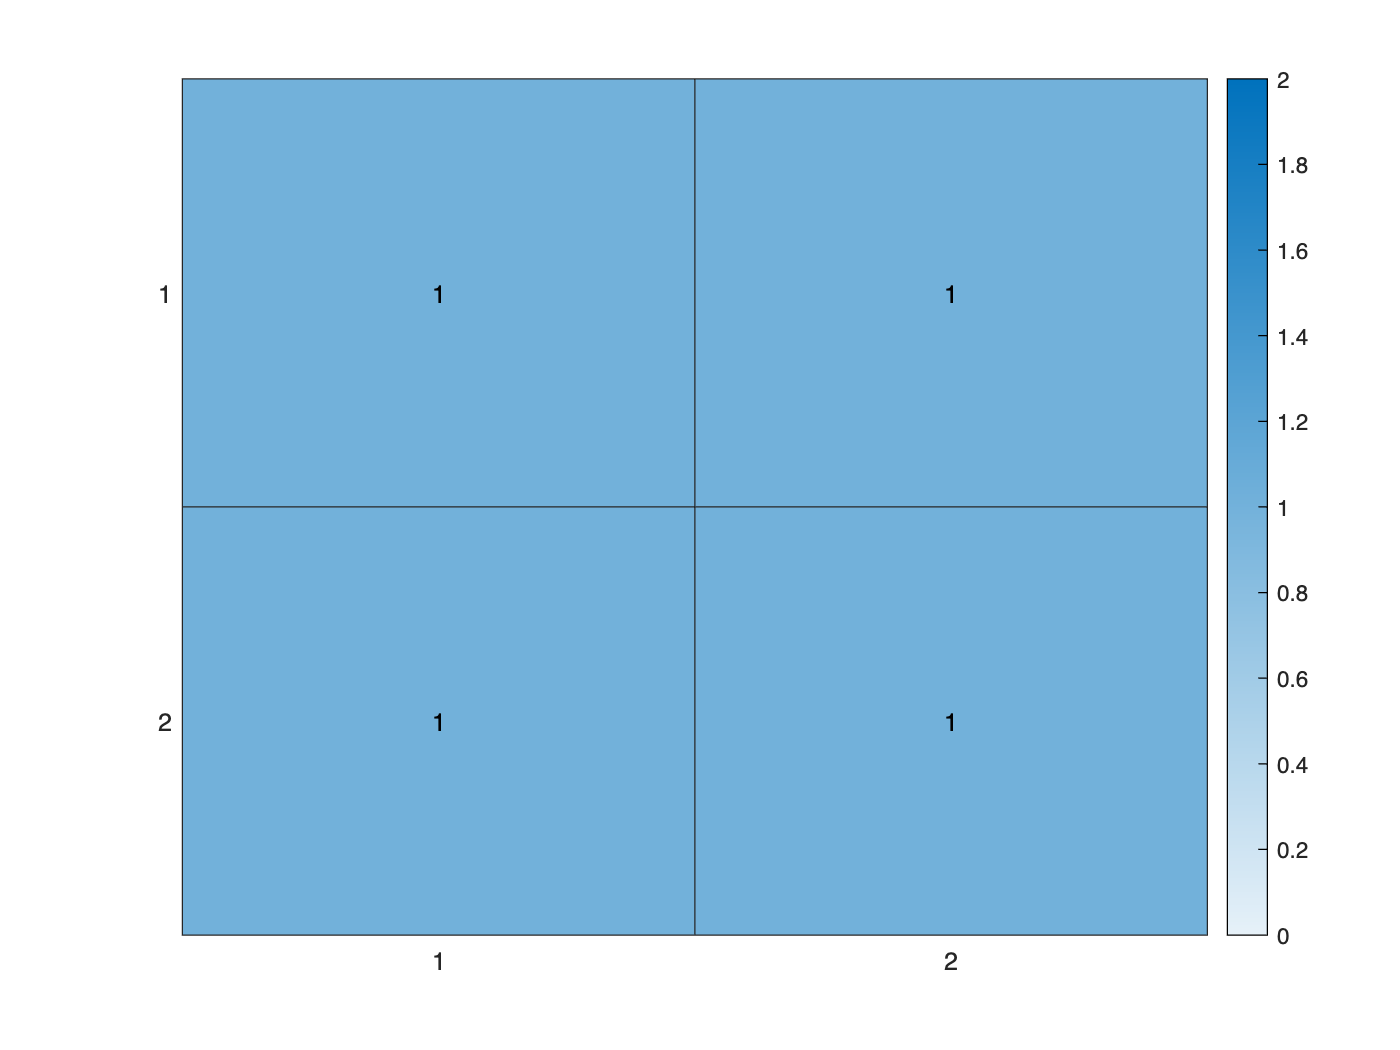

entropy(1,2) = -sum(jDist .* logcl(jDist) - jDist .* logcl(pB), 'all');
entropy(2,1) = -sum(jDist .* logcl(jDist) - jDist .* logcl(pA), 'all');

heatmap(entropy)

function [ent] = binent(p)
    if p == 0
        ent = 0;
        return;
    end
    ent = - (p.*logcl(p) + (1-p).*logcl(1-p));
end

function [y] = logcl(x)
    mask = x<=0;
    y = log2(x);
    y(mask) = 0;
end
